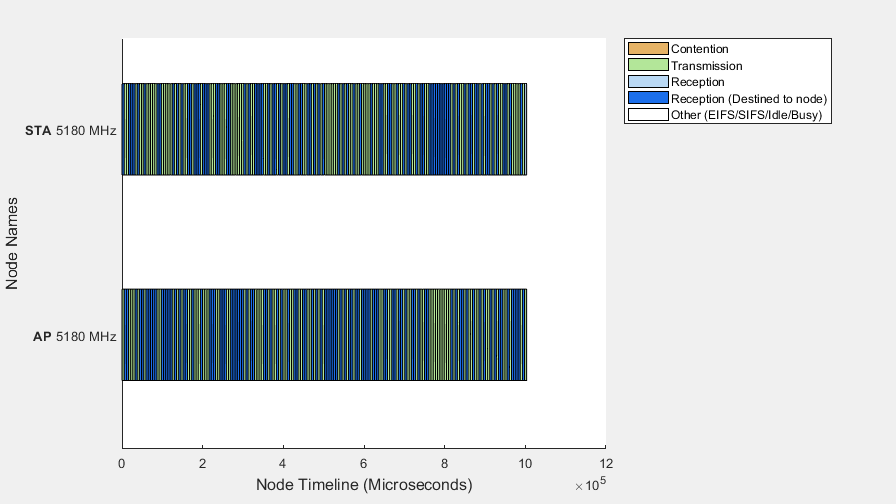

rng(1,"combRecursive")
simulationTime = 1;
showLiveStateTransitionPlot = true;
MACFrameAbstraction = false;
PHYAbstractionMethod = "tgax-evaluation-methodology";
networkSimulator = wirelessNetworkSimulator.init;
accessPointCfg = wlanDeviceConfig(Mode="AP",MCS=2,TransmitPower=15); % AP device configuration
stationCfg = wlanDeviceConfig(Mode="STA",MCS=2,TransmitPower=15);    % STA device configuration
accessPoint = wlanNode(Name="AP", ...
    Position=[10 0 0], ...
    DeviceConfig=accessPointCfg, ...
    PHYAbstractionMethod=PHYAbstractionMethod, ...
    MACFrameAbstraction=MACFrameAbstraction);

station = wlanNode(Name="STA", ...
    Position=[20 0 0], ...
    DeviceConfig=stationCfg, ...
    PHYAbstractionMethod=PHYAbstractionMethod, ...
    MACFrameAbstraction=MACFrameAbstraction);
nodes = [accessPoint station];
hCheckWLANNodesConfiguration(nodes)
associateStations(accessPoint,station,FullBufferTraffic="on");
channel = hSLSTGaxMultiFrequencySystemChannel(nodes);
addChannelModel(networkSimulator,channel.ChannelFcn)
capturePacketsFlag = true;
if capturePacketsFlag
    clear capturePacketsObj;                       % Clear existing helper object
    capturePacketsObj = hExportWLANPackets(nodes);
end
addNodes(networkSimulator,nodes)
viewerObj = hSimulationPlotViewer(showLiveStateTransitionPlot,nodes);
run(networkSimulator,simulationTime);

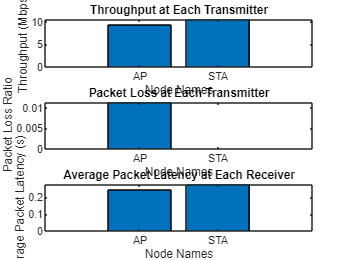

stats = statistics(nodes);
plotNetworkStats(viewerObj,simulationTime)

if capturePacketsFlag
    delete(capturePacketsObj.PCAPObjList);
end
% trafficSourceDL = networkTrafficOnOff(DataRate=100000,PacketSize=1500);
% trafficSourceUL = networkTrafficOnOff(DataRate=100000,PacketSize=1500);
% addTrafficSource(accessPoint,trafficSourceDL,DestinationNode=station,AccessCategory=0);
% addTrafficSource(station,trafficSourceUL,DestinationNode=accessPoint,AccessCategory=0);
